# **Brain-behaviour corr in the tbfMRI choir-singing dataset: verbal learning**

clear all
% Specify directories and patients
data_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/post-pre_diff_images/TU/';
data_path2='/Volumes/LASA/Aphasia_project/tb-fMRI/results/post-pre_diff_images/TU_TP12/';
mask_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/';
code_path='/Volumes/LASA/Aphasia_project/manuscripts/fMRI_SciRep/code/brainbeh/';
addpath(code_path) %add code path

First, we will extract the values from the significant behavioural variables for each patient:

% Import behavioural data and extract variables for the fMRI sample
importfile_verbalT(fullfile(code_path,'LASA_verbal_learning_pairedT_N19.csv'));
ID_BIDS_T_all=ans.ID_BIDS;
C1_T_all=ans.TRvsUTR_C_syll_postvspre;
C2_T_all=ans.TRvsUTR_C_and_alm_C_syll_postvspre;
C3_T_all=ans.TRvsUTR_C_minus_errors_syll_postvspre;
C4_T_all=ans.TRvsUTR_C_words_postvspre;
clear ans
importfile_verbalF(fullfile(code_path,'LASA_verbal_learning_flex_N19.csv'));
ID_BIDS_F_all=ans.ID_BIDS;
C1_F_all=ans.UU_C_syll_2vs1;
C2_F_all=ans.UU_C_and_alm_C_syll_2vs1;
C3_F_all=ans.UU_C_minus_errors_syll_2vs1;
C4_F_all=ans.UU_C_words_2vs1;

Second, we will extract the average intensity values from the clusters with significant results in the paired T-test and flexible factorial for the corresponding contrasts

% Save contrast name to variable
contrast1='Sing_along>Baseline';
mask1name='singavsrest_trainedvsuntrained_cluster_bin.nii';
mask2name='AB>BAxTP2>TP1_FWEc_cluster_bin.nii';

## Contrast 1: Paired T test Tydyy-Uulaa Sing along vs Rest

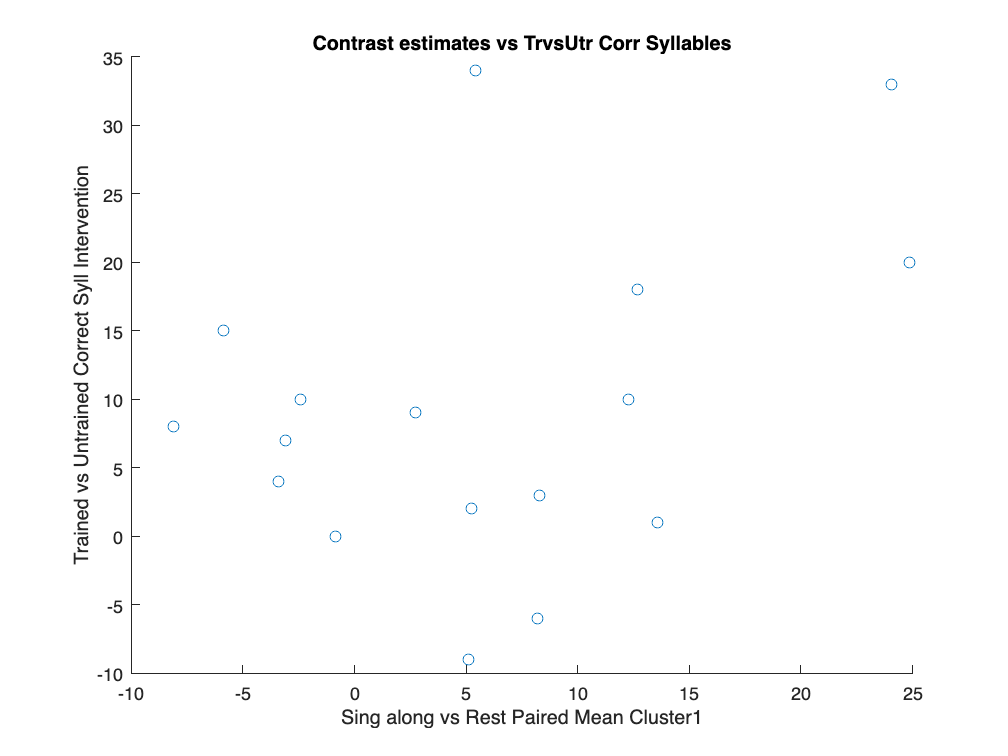

% Get the image filenames
filenames_contrast1= dir(fullfile(data_path,contrast1));
filenames_contrast1(ismember({filenames_contrast1.name},{'.','..'}))=[];

% Get L2 mask indices from FWEc cluster
    mask1=spm_vol(fullfile(mask_path,'paired T test/singa_vs_rest_TrainedvsUntrained_Age_TIV_wo_motion_outliers_wo_14_expmaskBRAVE/',mask1name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask1);
    mask1_idx=find(M~=0);
    mask1_int=mean(M(mask1_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1,1)
    V=spm_vol(fullfile(data_path,contrast1,filenames_contrast1(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_int=mean(Y(mask1_idx));
    [~,name,ext] =fileparts(filenames_contrast1(i).name);
    pa_int_mask1{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_mask1{i,2}=mean_int;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_mask1(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_T_all,ID_BIDS_pat);
C1_T_pat_contrast1=C1_T_all(iall,:);
C2_T_pat_contrast1=C2_T_all(iall,:);
C3_T_pat_contrast1=C3_T_all(iall,:);
C4_T_pat_contrast1=C4_T_all(iall,:);

%%%% CORRECT SYLLABLES%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(C1_T_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(C1_T_pat_contrast1(:,1)));
    C1_T_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_C1_T=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_C1_T(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=C1_T_pat_contrast1;
        if exist('pa_int_mask1_C1_T')==1
            x=pa_int_mask1_C1_T;
        else
            x=cell2mat(pa_int_mask1(:,2));
        end
        figure
        scatter(x,y)
        title ('Contrast estimates vs TrvsUtr Corr Syllables'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Trained vs Untrained Correct Syll Intervention')
        cd(fullfile(code_path,'outputs','verbal'))
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_TrvsUtr_Corr_Syll_mean_cluster' num2str(p) '.jpg'])
        save('TrvsUtr_corr_syll_singavsrest_T_mean_cluster','x','y')
        TrvsUtr_corr_syll_singavsrest_T=table(x,y);
        writetable(TrvsUtr_corr_syll_singavsrest_T, 'TrvsUtr_corr_syll_singavsrest_T_mean_cluster.xlsx');
end

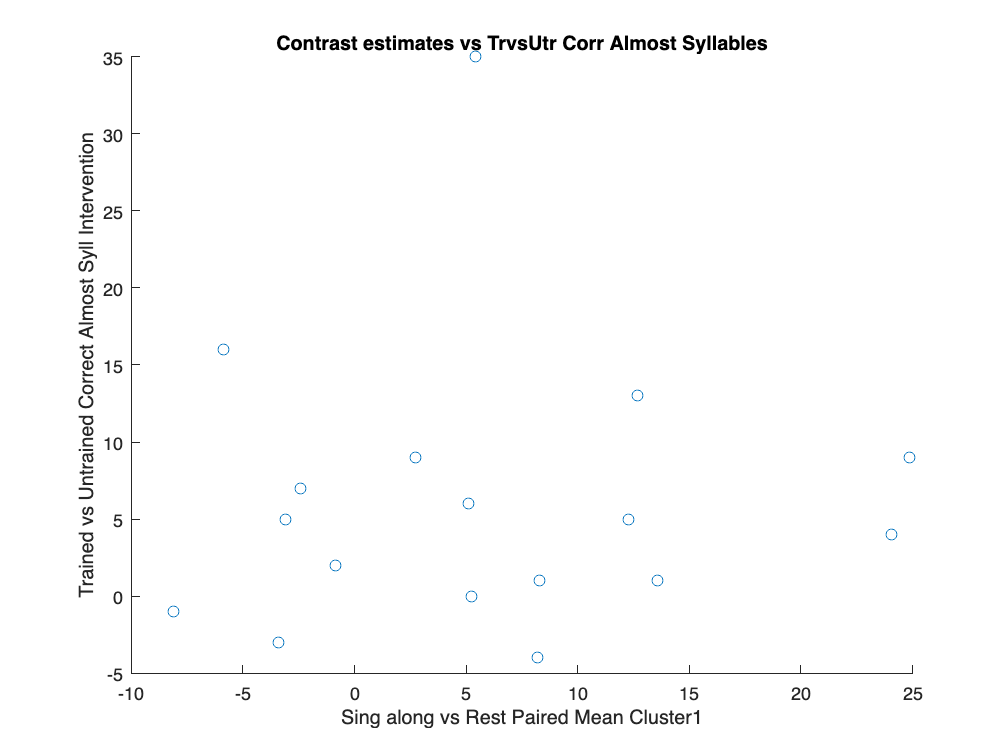


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson');
save('CorrSyl_Pearson_singavsrest_pairedT_mean_cluster','rho_mask1','pval_mask1')
[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V NAN_Index_contrast1

%%%%CORRECT AND ALMOST CORRECT SYLLABLES%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(C2_T_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(C2_T_pat_contrast1(:,1)));
    C2_T_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_C2_T=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_C2_T(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=C2_T_pat_contrast1;
        if exist('pa_int_mask1_C2_T')==1
            x=pa_int_mask1_C2_T;
        else
            x=cell2mat(pa_int_mask1(:,2));
        end
        figure
        scatter(x,y)
        title ('Contrast estimates vs TrvsUtr Corr Almost Syllables'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Trained vs Untrained Correct Almost Syll Intervention')
        cd(fullfile(code_path,'outputs','verbal'))
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_TrvsUtr_Corr_Alm_Syll_mean_cluster' num2str(p) '.jpg'])
        save('TrvsUtr_corr_alm_syll_singavsrest_T_mean_cluster','x','y')
        TrvsUtr_corr_alm_syll_singavsrest_T=table(x,y);
        writetable(TrvsUtr_corr_alm_syll_singavsrest_T, 'TrvsUtr_corr_alm_syll_singavsrest_T_mean_cluster.xlsx');
end

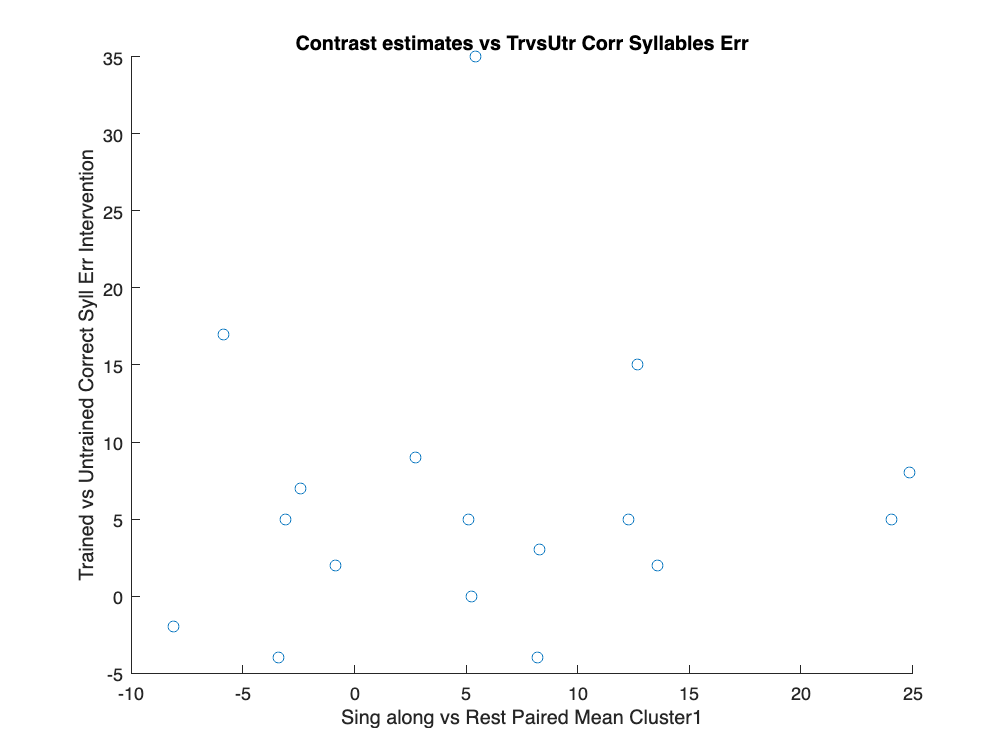


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson');
save('CorrAlmSyl_Pearson_singavsrest_pairedT_mean_cluster','rho_mask1','pval_mask1')
[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V NAN_Index_contrast1

%%%%CORRECT SYLLABLES MINUS ERRORS%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(C3_T_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(C3_T_pat_contrast1(:,1)));
    C3_T_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_C3_T=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_C3_T(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=C3_T_pat_contrast1;
        if exist('pa_int_mask1_C3_T')==1
            x=pa_int_mask1_C3_T;
        else
            x=cell2mat(pa_int_mask1(:,2));
        end
        figure
        scatter(x,y)
        title ('Contrast estimates vs TrvsUtr Corr Syllables Err'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Trained vs Untrained Correct Syll Err Intervention')
        cd(fullfile(code_path,'outputs','verbal'))
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_TrvsUtr_Corr_Syll_Err_mean_cluster' num2str(p) '.jpg'])
        save('TrvsUtr_corr_syll_err_singavsrest_T_mean_cluster','x','y')
        TrvsUtr_corr_syll_err_singavsrest_T=table(x,y);
        writetable(TrvsUtr_corr_syll_err_singavsrest_T, 'TrvsUtr_corr_syll_err_singavsrest_T_mean_cluster.xlsx');
end

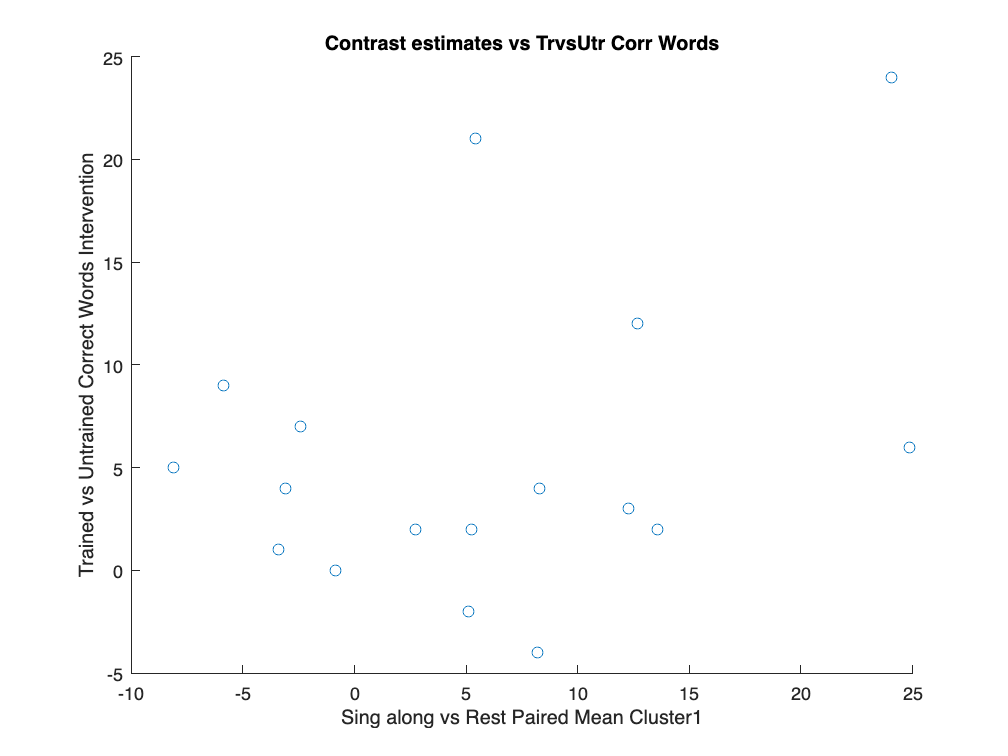


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson');
save('CorrSylErr_Pearson_singavsrest_pairedT_mean_cluster','rho_mask1','pval_mask1')
[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V NAN_Index_contrast1

%%%%CORRECT WORDS%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(C4_T_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(C4_T_pat_contrast1(:,1)));
    C4_T_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_C4_T=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_C4_T(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=C4_T_pat_contrast1;
        if exist('pa_int_mask1_C4_T')==1
            x=pa_int_mask1_C4_T;
        else
            x=cell2mat(pa_int_mask1(:,2));
        end
        figure
        scatter(x,y)
        title ('Contrast estimates vs TrvsUtr Corr Words'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Trained vs Untrained Correct Words Intervention')
        cd(fullfile(code_path,'outputs','verbal'))
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_TrvsUtr_Corr_Words_mean_cluster' num2str(p) '.jpg'])
        save('TrvsUtr_corr_words_singavsrest_T_mean_cluster','x','y')
        TrvsUtr_corr_words_singavsrest_T=table(x,y);
        writetable(TrvsUtr_corr_words_singavsrest_T, 'TrvsUtr_corr_words_singavsrest_T_mean_cluster.xlsx');
end


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson');
save('CorrWords_Pearson_singavsrest_pairedT_mean_cluster','rho_mask1','pval_mask1')
[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V NAN_Index_contrast1



## Contrast 1: Flexible AB>BAxTP2>TP1 Tydyy-Uulaa Sing along vs Rest

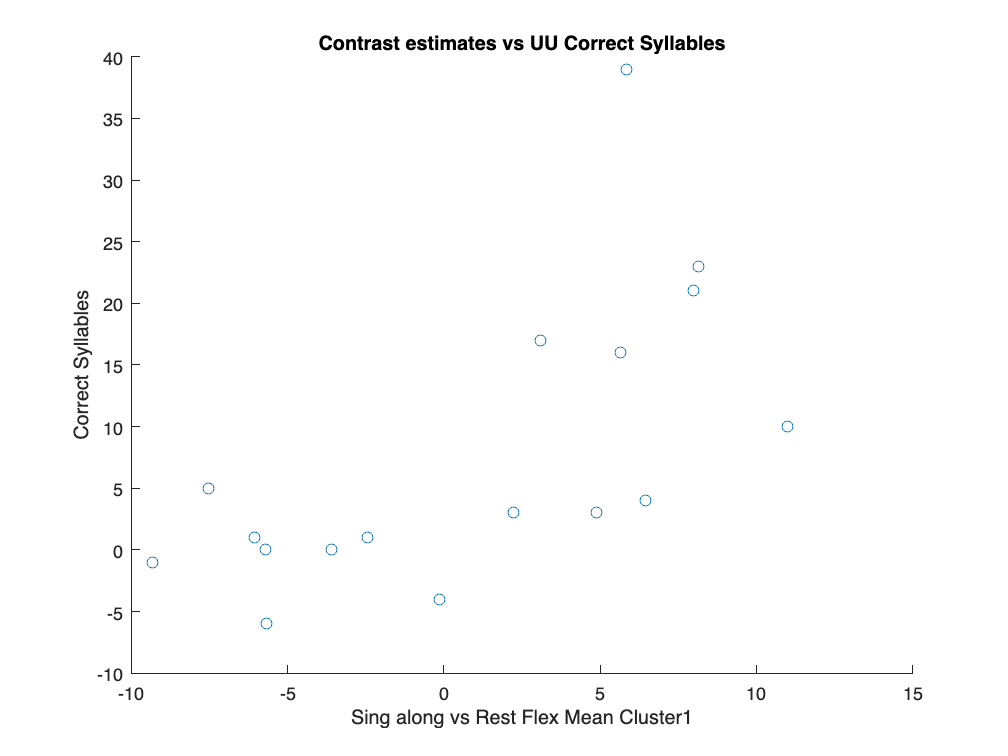

% Get the image filenames
filenames_contrast1f= dir(fullfile(data_path2,contrast1));
filenames_contrast1f(ismember({filenames_contrast1f.name},{'.','..'}))=[];
% Get L2 mask indices from FWEc cluster
    mask2=spm_vol(fullfile(mask_path,'flexible factorial/singa_vs_rest_TU_2by2_Age_TIV_WABAQ_expmaskBRAVE/',mask2name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask2);
    mask2_idx=find(M~=0);
    mask2_int=mean(M(mask2_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1f,1)
    V=spm_vol(fullfile(data_path2,contrast1,filenames_contrast1f(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_21=mean(Y(mask2_idx));
    [~,name,ext] =fileparts(filenames_contrast1f(i).name);
    pa_21_mask2{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_21_mask2{i,2}=mean_21;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_21_mask2(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_F_all,ID_BIDS_pat);
C1_F_pat_contrast1=C1_F_all(iall,:);
C2_F_pat_contrast1=C2_F_all(iall,:);
C3_F_pat_contrast1=C3_F_all(iall,:);
C4_F_pat_contrast1=C4_F_all(iall,:);

%%%%CORRECT SYLLABLES%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(C1_F_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(C1_F_pat_contrast1(:,1)));
    C1_F_pat_contrast1(NAN_Index_contrast1f,:)=[];
    pa_21_mask2_C1_F=cell2mat(pa_21_mask2(:,2));
    pa_21_mask2_C1_F(NAN_Index_contrast1f,:)=[];
end
    
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=C1_F_pat_contrast1;
           if exist('pa_21_mask2_C1_F')==1
            x= pa_21_mask2_C1_F;
        else
            x=cell2mat(pa_21_mask2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU Correct Syllables'), xlabel(['Sing along vs Rest Flex Mean Cluster' num2str(p)]), ylabel ('Correct Syllables')
        cd(fullfile(code_path,'outputs','verbal'))
        saveas(gcf,['scatter_betas_flex_SingavsRest_UU_Correct_Syllables_mean_cluster' num2str(p) '.jpg'])
        save('UU_Corr_Syll_21_singavsrest_flex_mean_cluster','x','y')
        C1_F_singavsrest_F=table(x,y);
        writetable(C1_F_singavsrest_F, 'UU_corr_syll_singavsrest_F_mean_cluster.xlsx');
end

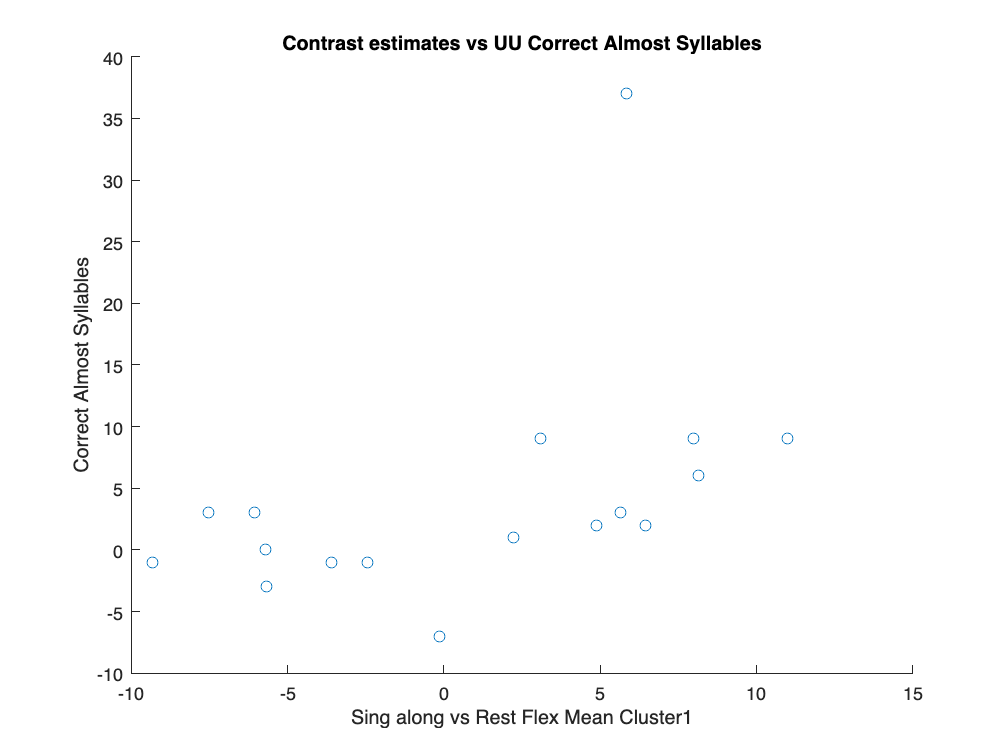

% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson');
save('CorrSyl_Pearson_singavsrest_flex_mean_cluster','rho_mask1','pval_mask1')
[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V NAN_Index_contrast1

%%%%CORRECT AND ALMOST CORRECT SYLLABLES%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(C2_F_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(C2_F_pat_contrast1(:,1)));
    C2_F_pat_contrast1(NAN_Index_contrast1f,:)=[];
    pa_21_mask2_C2_F=cell2mat(pa_21_mask2(:,2));
    pa_21_mask2_C2_F(NAN_Index_contrast1f,:)=[];
end
    
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=C2_F_pat_contrast1;
           if exist('pa_21_mask2_C2_F')==1
            x= pa_21_mask2_C2_F;
        else
            x=cell2mat(pa_21_mask2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU Correct Almost Syllables'), xlabel(['Sing along vs Rest Flex Mean Cluster' num2str(p)]), ylabel ('Correct Almost Syllables')
        cd(fullfile(code_path,'outputs','verbal'))
        saveas(gcf,['scatter_betas_flex_SingavsRest_UU_Correct_Almost_Syllables_mean_cluster' num2str(p) '.jpg'])
        save('UU_Corr_Alm_Syll_21_singavsrest_flex_mean_cluster','x','y')
        C2_F_singavsrest_F=table(x,y);
        writetable(C2_F_singavsrest_F, 'UU_corr_alm_syll_singavsrest_F_mean_cluster.xlsx');
end

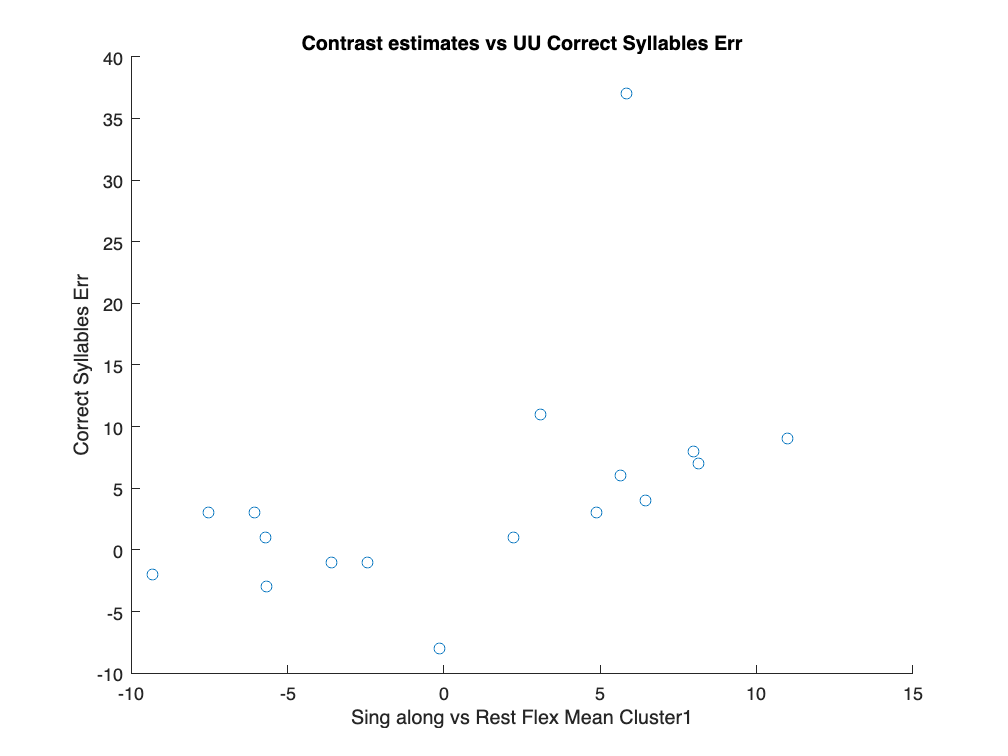


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson');
save('CorrAlmSyl_Pearson_singavsrest_flex_mean_cluster','rho_mask1','pval_mask1')
[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V NAN_Index_contrast1

%%%%CORRECT MINUS ERRORS SYLLABLES%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(C3_F_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(C3_F_pat_contrast1(:,1)));
    C3_F_pat_contrast1(NAN_Index_contrast1f,:)=[];
    pa_21_mask2_C3_F=cell2mat(pa_21_mask2(:,2));
    pa_21_mask2_C3_F(NAN_Index_contrast1f,:)=[];
end
    
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=C3_F_pat_contrast1;
           if exist('pa_21_mask2_C3_F')==1
            x= pa_21_mask2_C3_F;
        else
            x=cell2mat(pa_21_mask2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU Correct Syllables Err'), xlabel(['Sing along vs Rest Flex Mean Cluster' num2str(p)]), ylabel ('Correct Syllables Err')
        cd(fullfile(code_path,'outputs','verbal'))
        saveas(gcf,['scatter_betas_flex_SingavsRest_UU_Correct_Syllables_Err_mean_cluster' num2str(p) '.jpg'])
        save('UU_Corr_Syll_Err_21_singavsrest_flex_mean_cluster','x','y')
        C3_F_singavsrest_F=table(x,y);
        writetable(C3_F_singavsrest_F, 'UU_corr_syll_err_singavsrest_F_mean_cluster.xlsx');
end

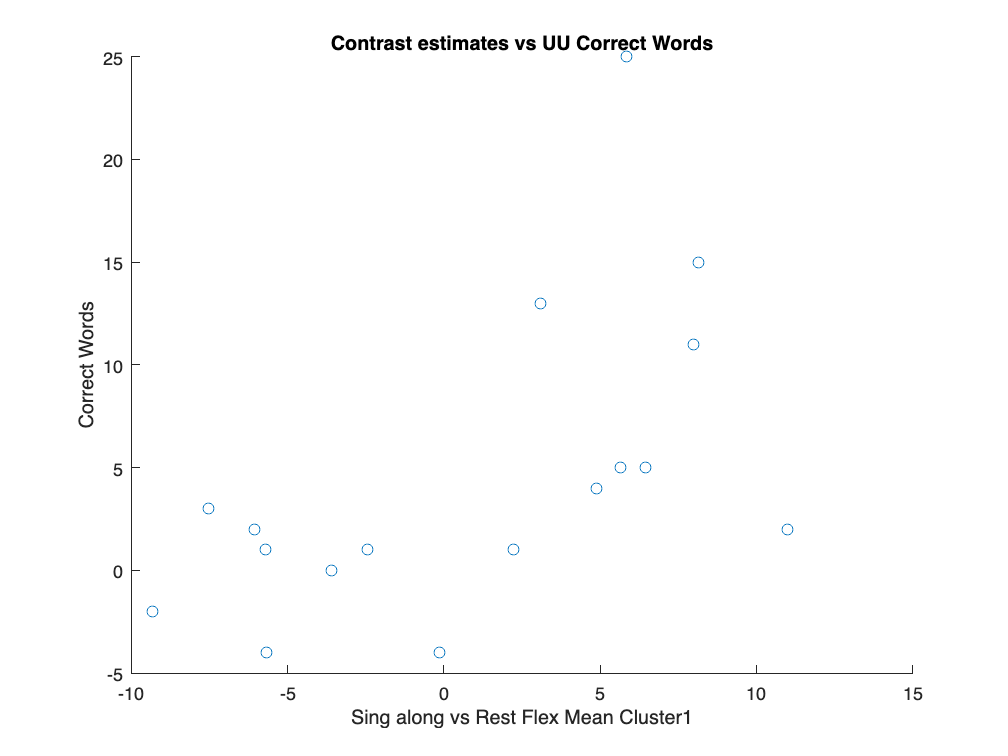


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson');
save('CorrSylErr_Pearson_singavsrest_flex_mean_cluster','rho_mask1','pval_mask1')
[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V NAN_Index_contrast1

%%%%CORRECT WORDS%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(C4_F_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(C4_F_pat_contrast1(:,1)));
    C4_F_pat_contrast1(NAN_Index_contrast1f,:)=[];
    pa_21_mask2_C4_F=cell2mat(pa_21_mask2(:,2));
    pa_21_mask2_C4_F(NAN_Index_contrast1f,:)=[];
end
    
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=C4_F_pat_contrast1;
           if exist('pa_21_mask2_C4_F')==1
            x= pa_21_mask2_C4_F;
        else
            x=cell2mat(pa_21_mask2(:,2));
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU Correct Words'), xlabel(['Sing along vs Rest Flex Mean Cluster' num2str(p)]), ylabel ('Correct Words')
        cd(fullfile(code_path,'outputs','verbal'))
        saveas(gcf,['scatter_betas_flex_SingavsRest_UU_Correct_Words_mean_cluster' num2str(p) '.jpg'])
        save('UU_Corr_Words_21_singavsrest_flex_mean_cluster','x','y')
        C4_F_singavsrest_F=table(x,y);
        writetable(C4_F_singavsrest_F, 'UU_corr_words_singavsrest_F_mean_cluster.xlsx');
end


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson');
save('CorrWords_Pearson_singavsrest_flex_mean_cluster','rho_mask1','pval_mask1')
[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V NAN_Index_contrast1